# BME 3053C Final Project

Group Members: Grace Cabrera, Mahmoud Fakhouri, Isabel Munoz, April Olson

Course: BME 3053C Computer Applications for BME

Term: Fall 2020

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: Grace's, mahmoud.fakhouri@ufl.edu, Isabel's, aprilolson@ufl.edu

December 15, 2020

## Preparation Steps

Reading Image File

clc; clear; close all;
userinput = input('Enter file name: ' , 's');
image = imread(userinput);

Extracting Color Channels

R = image(:,:,1);
G = image(:,:,2);
B = image(:,:,3);

## Vein Segmentation

Making Image Border Black

mask = G > 10;
G(~mask) = 0;

Finding Average Intensity Value

i = 1;
count = 0;
num = numel(G);
while i <= num
    if G(i) > 0
        count = count+1;
    end
    i = i+1;
end
add = sum(G(:));
avg = add/count;

Binarizing Image

I = imbinarize(G,'adaptive','ForegroundPolarity','dark','Sensitivity',0.53);

Invert Binary Image

I = imcomplement(I);

Dilate

se90 = strel('line',3,90); 
se0 = strel('line',3,0);
I = imdilate(I,[se90 se0]); 

Clear small areas

I = bwareafilt(I, 100);

Smooth Image

seD=strel('diamond',1);
I=imerode(I,seD);

Reducing Patches

[h,w] = size(I);
I2 = I;
for i = 1:50
    for j = 1:100
        start_row = floor(1+h/50*i-h/50);
        end_row = floor(h/50*i);
        start_col = floor(1+w/100*j-w/100);
        end_col = floor(w/100*j);
        average = mean(I(start_row:1:end_row,start_col:1:end_col));
        if average > 0.7
            I2(start_row:1:end_row,start_col:1:end_col) = 0;
        end
    end
end
I = I2;

## Optic Ratio

Thresholding Red Channel

cup = R<=255 & R > 253;
disc = R <= 253 & R > 240;

Filling Holes

cup = imfill(cup,'holes'); 
disc = imfill(disc,'holes'); 

Dilate

se90 = strel('line',4,90); 
se0 = strel('line',4,0);
cup = imdilate(cup,[se90 se0]); 
disc = imdilate(disc,[se90 se0]); 

Clear Border of Cup

cup = imclearborder(cup);
se1=strel('disk',2);
di=imdilate(cup,se1);
cup=di;

Clear Border of Disc

disc = imclearborder(disc);
se1=strel('disk',2);
di=imdilate(disc,se1);
disc=di;

Removing All Small Areas

cup = bwareafilt(cup, 1);
disc = bwareafilt(disc, 1);


Run through image segmenter to find disc (this further cleans up image)

disc=255*repmat(uint8(disc),1,1,3);
[disc,~]=segmentImage(disc);

Finding Diameter of Cup

[r1,c1] = size(cup);
hlengths1 = [];
for i = 1:r1
    row1 = nnz(cup(i, :));
    hlengths1 = [hlengths1 row1];
end
HorizontalDiameter1 = max(hlengths1);
vlengths1 = [];
for i = 1:c1
    column1 = nnz(cup(:, i));
    vlengths1 = [vlengths1 column1];
end
VerticalDiameter1 = max(vlengths1);

TrueCupDiameter = (HorizontalDiameter1 + VerticalDiameter1)/2;

Finding Diameter of Disc

[r2,c2] = size(disc);
hlengths2 = [];
for i = 1:r2
    row2 = nnz(disc(i, :));
    hlengths2 = [hlengths2 row2];
end
HorizontalDiameter2 = max(hlengths2);
vlengths2 = [];
for i = 1:c2
    column2 = nnz(disc(:, i));
    vlengths2 = [vlengths2 column2];
end
VerticalDiameter2 = max(vlengths2);

TrueDiscDiameter = (HorizontalDiameter2 + VerticalDiameter2)/2;

## Results

Displaying Results

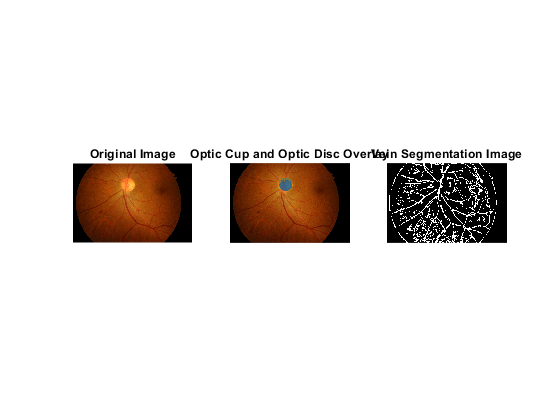

subplot(1,3,1);
imshow(image)
title('Original Image');
subplot(1,3,2);
cupoverlay = labeloverlay(image, cup);
finaloverlay = labeloverlay(cupoverlay, disc, 'Colormap','summer');
imshow(finaloverlay)
title('Optic Cup and Optic Disc Overlay');
subplot(1,3,3);
imshow(I)
title('Vein Segmentation Image');

CDR (Cup-to-Disc Ratio)

CDR = TrueCupDiameter/TrueDiscDiameter;
fprintf('The approximate Cup-to-Disc Ratio (CDR) is %.3f', CDR);

The approximate Cup-to-Disc Ratio (CDR) is 0.925

Categorizing Glaucoma From CDR

if CDR < 0.4 
    fprintf('The patient''s CDR does not indicate any signs of Glaucoma.')
elseif CDR < 0.8 && CDR >= 0.4
    fprintf('The patient''s CDR may indicate signs of Glaucoma.')
elseif CDR >= 0.8
    fprintf('The patient''s CDR suggests Glaucomatous Optic Neuropathy.')
end

The patient's CDR suggests Glaucomatous Optic Neuropathy.